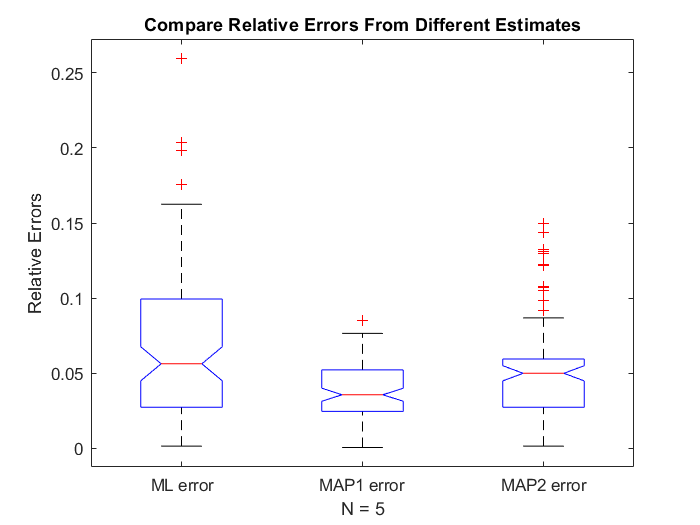

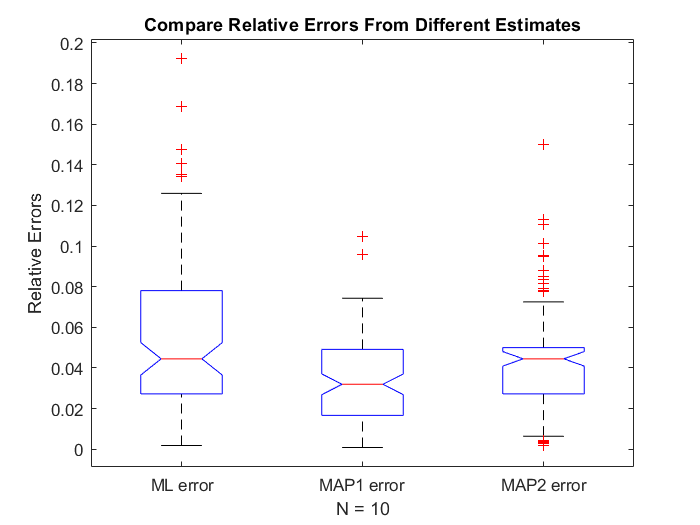

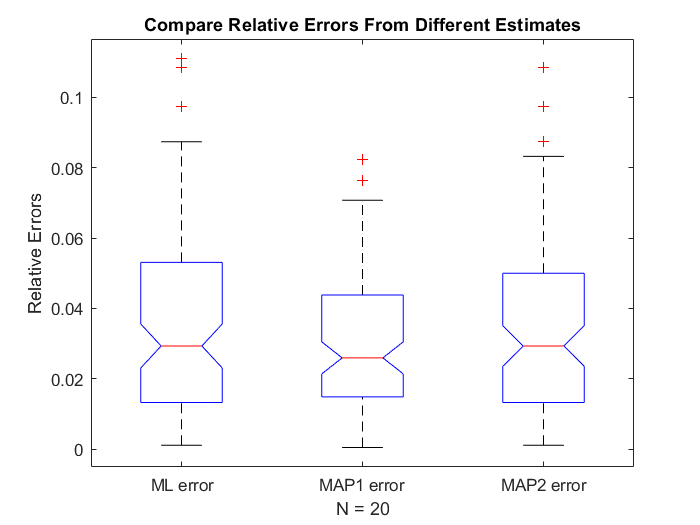

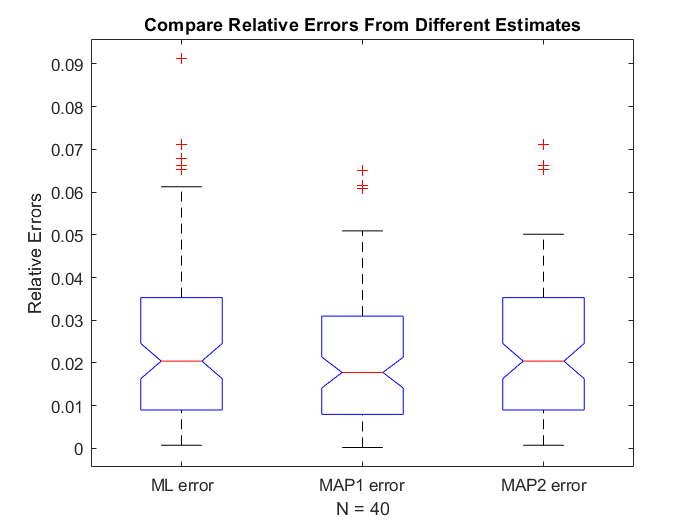

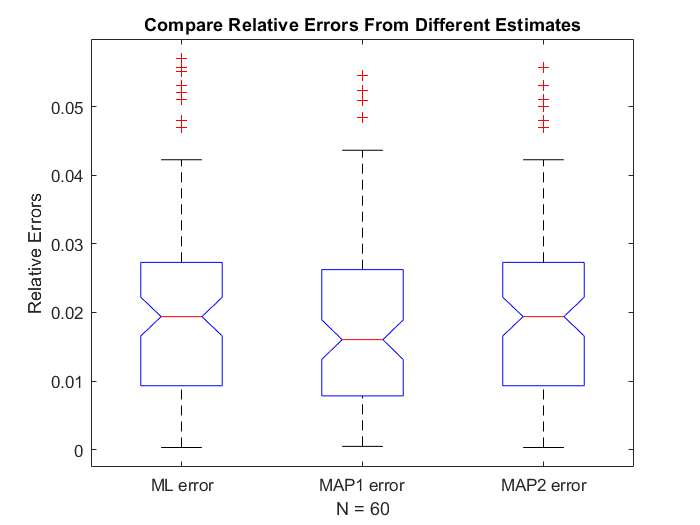

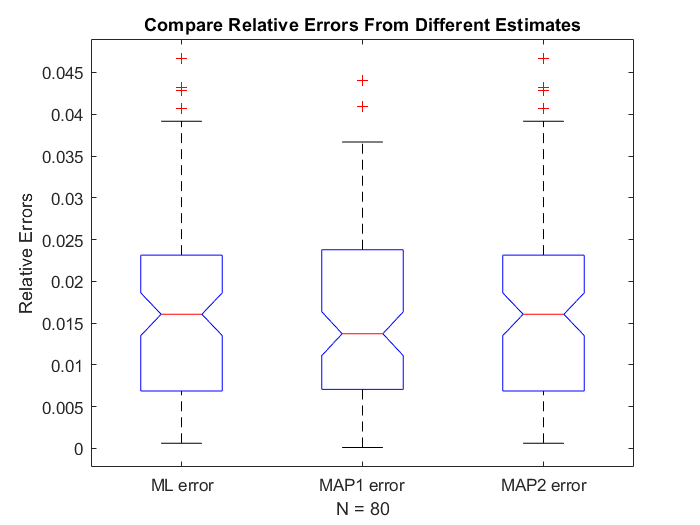

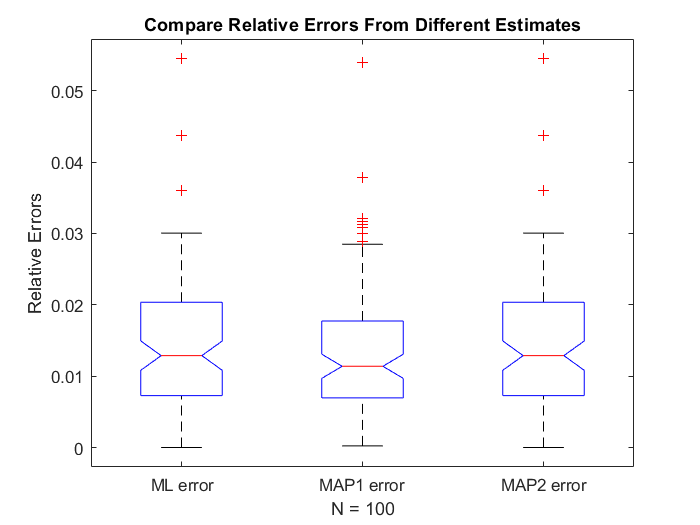

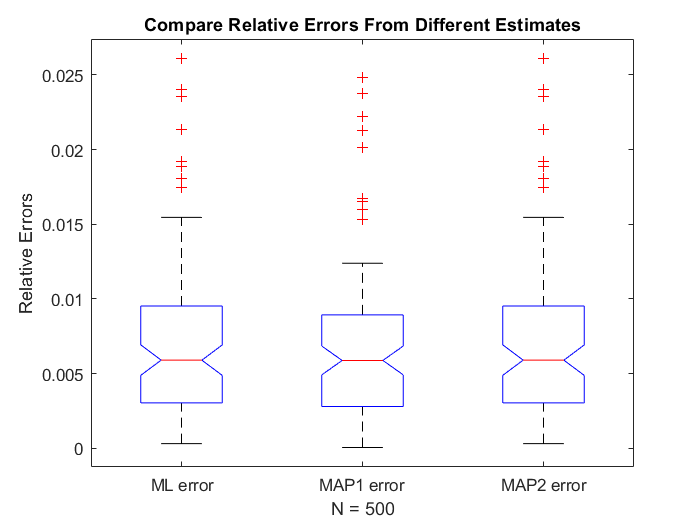

rng("default")

N = [5, 10, 20, 40, 60, 80, 100, 500, 1000 10000];
m = 100;
errors_ML = zeros(m,10);
errors_MAP1 = zeros(m,10);
errors_MAP2 = zeros(m,10);
for j = 1:10
    n = N(j);
    mean_true = 10;
    var_true = 16;
    error_ML = zeros(m,1);
    error_MAP1 = zeros(m,1);
    error_MAP2 = zeros(m,1);
    for i = 1:m
        data = 2*randn(1,n)+10;
        
        % Finding the ML estimate which is equal to sample mean
        sample_mean = sum(data)/n;
        mean_ML = sample_mean;
        
        % Considering a gaussian prior for the mean with mean 10.5 and standard deviation 1
        mean_0 = 10.5;
        var_0 = 1;
        
        mean_MAP1 = (sample_mean*var_0 + mean_0*var_true/n)/(var_true/n + var_0); 
        
        % Considering an uniform prior for the mean over 9.5 to 11.5
        % For an uniform prior the Posterior estimate:
        if (sample_mean < 9.5)
            mean_MAP2 = 9.5;
        elseif(sample_mean < 11.5)
            mean_MAP2 = sample_mean;
        else
            mean_MAP2 = 11.5;
        end
        error_ML(i,1) = abs(mean_ML - mean_true)/mean_true;
        error_MAP1(i,1) = abs(mean_MAP1-mean_true)/mean_true;
        error_MAP2(i,1) = abs(mean_MAP2 - mean_true)/mean_true;
    end
    figure
    boxplot([error_ML,error_MAP1,error_MAP2],'Notch','on','Labels',{'ML error','MAP1 error','MAP2 error'},'Whisker',1)
    title(sprintf('Compare Relative Errors From Different Estimates'))
    xlabel(sprintf('N = %d',n))
    ylabel('Relative Errors')
    errors_ML(:,j) = error_ML;
    errors_MAP1(:,j) = error_MAP1;
    errors_MAP2(:,j) = error_MAP2;
end

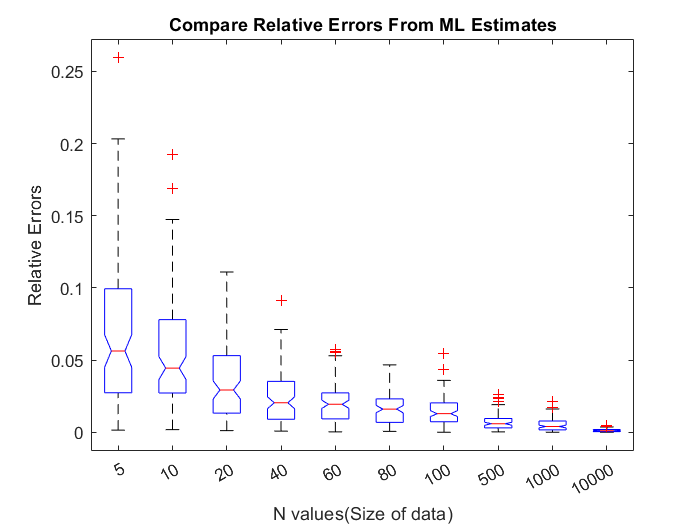

figure 
boxplot(errors_ML,'Notch','on','Labels',N)
title(sprintf('Compare Relative Errors From ML Estimates'))
xlabel(sprintf('N values(Size of data)'))
ylabel('Relative Errors')

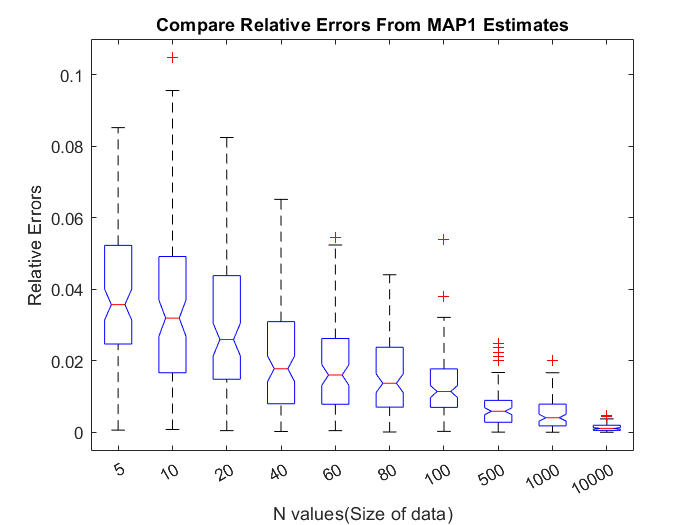

figure 
boxplot(errors_MAP1,'Notch','on','Labels',N)
title(sprintf('Compare Relative Errors From MAP1 Estimates'))
xlabel(sprintf('N values(Size of data)'))
ylabel('Relative Errors')

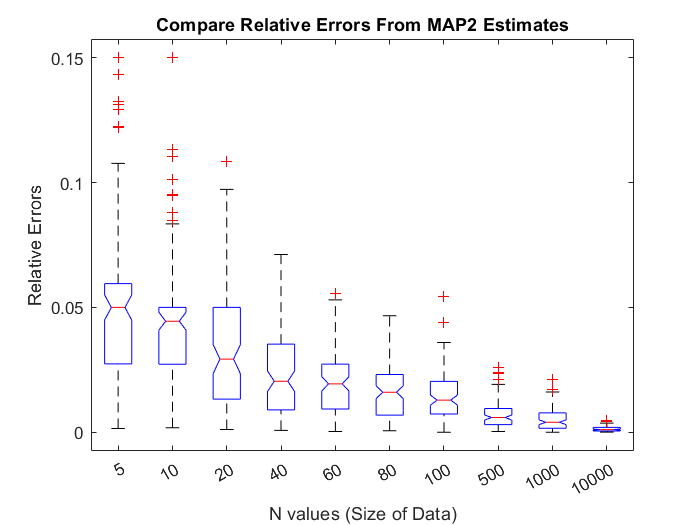

figure 
boxplot(errors_MAP2,'Notch','on','Labels',N)
title(sprintf('Compare Relative Errors From MAP2 Estimates'))
xlabel(sprintf('N values (Size of Data)'))
ylabel('Relative Errors')

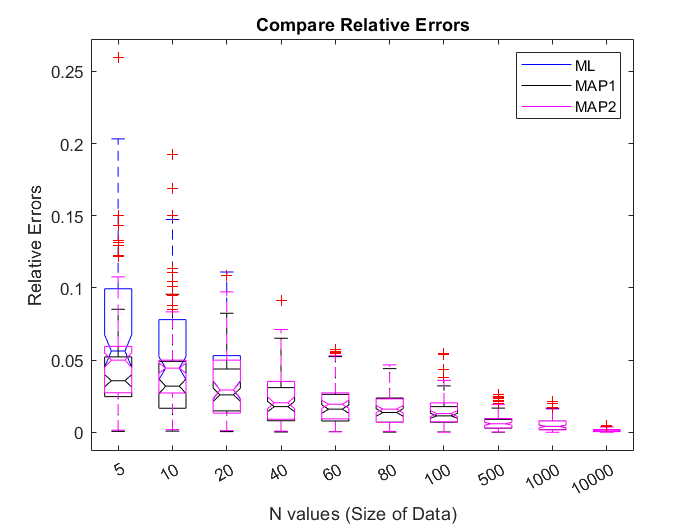

figure
boxplot(errors_ML, 'Colors',"b", 'Notch', 'on');
hold on;
boxplot(errors_MAP1, 'Colors',"k", 'Notch',"on");
boxplot(errors_MAP2, 'Colors',"m",'Notch','on', 'Labels',N);
xlabel('N values (Size of Data)');
ylabel('Relative Errors');
title('Compare Relative Errors');
plot(nan,'b');
plot(nan,'k');
plot(nan,'m');
legend('ML','MAP1','MAP2');
hold off;